G = get_full_graph(fullfile("additional_Files", "building_collider_list.csv"), true);

folder_path = fullfile("F:\big-data\vr_data\Data\preprocessing-pipeline\noises-vs-gazes");
p_table = create_glaucoma_participant_table(folder_path);

gaze_full_data = get_gaze_data(folder_path, p_table.PID', '_gazes_data_WB.mat');

query = p_table.category == "control";
control_parts = p_table(query, :);

#### Fixation Time filtering

- Fixation time mean (with and without correction)

- Fixation time for landmarks

- Fixation time including inside/outside (with and without correction)

- Number of Fixations

% remove noData newSession NH
% exclude participants
removed_clusters = ["noData", "newSession", "NH"];
query = ~any(string(gaze_full_data.hitObjectColliderName) == removed_clusters, 2);

clean_gaze_full_data = gaze_full_data(query, :);


% total fixation
no_fixation = groupsummary(clean_gaze_full_data, "PID");

% sum of cluster duration
collider_sum_gaze = groupsummary(clean_gaze_full_data, {'PID', 'hitObjectColliderName'}, 'sum', 'clusterDuration');

excluded_sum_gaze = collider_sum_gaze;

% only participants in control group
query = any(excluded_sum_gaze.PID == control_parts.PID', 2);
excluded_control_sum_gaze = excluded_sum_gaze(query,:);

% clean gaze data joined with participant table
gaze_full_group = join(clean_gaze_full_data, p_table);
gaze_full_group.category = reordercats(categorical(gaze_full_group.category), ["control", "glaucoma"]);
gaze_full_group.hitObjectColliderName = categorical(gaze_full_group.hitObjectColliderName);
gaze_full_group.PID = categorical(gaze_full_group.PID);
gaze_full_group.clusterDuration = gaze_full_group.clusterDuration / 1000;

% custom filter to evaluate gaze
query = gaze_full_group.clusterDuration < 5;
gaze_full_group_cut = gaze_full_group(query, :);

#### Common Building Filter

the buildings that are seen by control participants are considered as common buildings.

common_buildings = G.Nodes.Name;
cur_parts = unique(excluded_control_sum_gaze.PID);

for control = cur_parts'
    query = excluded_control_sum_gaze.PID == control;
    cur_excluded_control_sum_gaze = excluded_control_sum_gaze(query, :)
    cur_buildings = cur_excluded_control_sum_gaze.hitObjectColliderName;
    common_buildings = intersect(common_buildings, cur_buildings);
end

cur_excluded_control_sum_gaze = 76×4 table
    PID     hitObjectColliderName    GroupCount    sum_clusterDuration
    ____    _____________________    __________    ___________________

    2002      {'Building_100'}           10              4512.6       
    2002      {'Building_101'}           21               12569       
    2002      {'Building_102'}            4              4515.6       
    2002      {'Building_108'}            2              1043.3       
    2002      {'Building_109'}            1              267.73       
    2002      {'Building_140'}            1              288.74       
    2002      {'Building_141'}            4              1411.2       
    2002      {'Building_144'}            7              2808.5       
    2002      {'Building_145'}            8              7618.8       
    2002      {'Building_146'}         

cur_excluded_control_sum_gaze = 77×4 table
    PID     hitObjectColliderName    GroupCount    sum_clusterDuration
    ____    _____________________    __________    ___________________

    2005      {'Building_100'}           15                6370       
    2005      {'Building_101'}           16              8149.9       
    2005      {'Building_102'}            2              631.59       
    2005      {'Building_108'}            1              377.31       
    2005      {'Building_139'}            1              389.82       
    2005      {'Building_140'}            6              2451.7       
    2005      {'Building_141'}            6              2257.9       
    2005      {'Building_142'}            9              5497.4       
    2005      {'Building_144'}           11              8404.3       
    2005      {'Building_145'}         

cur_excluded_control_sum_gaze = 76×4 table
    PID     hitObjectColliderName    GroupCount    sum_clusterDuration
    ____    _____________________    __________    ___________________

    2006      {'Building_100'}           14              6773.9       
    2006      {'Building_101'}            6              2900.4       
    2006      {'Building_102'}           11              7040.6       
    2006      {'Building_139'}            4              1920.4       
    2006      {'Building_141'}            4              1701.4       
    2006      {'Building_144'}            6              2299.5       
    2006      {'Building_145'}           10               12686       
    2006      {'Building_146'}            2              820.66       
    2006      {'Building_147'}            8                5086       
    2006      {'Building_148'}         

cur_excluded_control_sum_gaze = 60×4 table
    PID     hitObjectColliderName    GroupCount    sum_clusterDuration
    ____    _____________________    __________    ___________________

    2007      {'Building_100'}            3              934.44       
    2007      {'Building_101'}            1              342.21       
    2007      {'Building_139'}            2              893.22       
    2007      {'Building_140'}            2              589.12       
    2007      {'Building_141'}           13              6443.6       
    2007      {'Building_142'}            1              566.43       
    2007      {'Building_144'}            6              2190.1       
    2007      {'Building_145'}           11              6827.1       
    2007      {'Building_146'}            3              3176.8       
    2007      {'Building_147'}         

cur_excluded_control_sum_gaze = 80×4 table
    PID     hitObjectColliderName    GroupCount    sum_clusterDuration
    ____    _____________________    __________    ___________________

    2008      {'Building_100'}            6              2122.7       
    2008      {'Building_101'}           16               11508       
    2008      {'Building_102'}           15                6980       
    2008      {'Building_108'}            4              2898.8       
    2008      {'Building_139'}            3                1356       
    2008      {'Building_140'}            7              6838.5       
    2008      {'Building_141'}            2              688.87       
    2008      {'Building_142'}            6              5319.2       
    2008      {'Building_144'}           15              7559.4       
    2008      {'Building_145'}         

cur_excluded_control_sum_gaze = 92×4 table
    PID     hitObjectColliderName    GroupCount    sum_clusterDuration
    ____    _____________________    __________    ___________________

    2009      {'Building_100'}           12              4560.5       
    2009      {'Building_101'}           19              7363.4       
    2009      {'Building_102'}            9              3620.5       
    2009      {'Building_107'}            1              289.51       
    2009      {'Building_108'}            1              943.15       
    2009      {'Building_109'}            1              378.26       
    2009      {'Building_137'}            4              3676.2       
    2009      {'Building_139'}            1              454.43       
    2009      {'Building_140'}            3              1266.3       
    2009      {'Building_141'}         

cur_excluded_control_sum_gaze = 82×4 table
    PID     hitObjectColliderName    GroupCount    sum_clusterDuration
    ____    _____________________    __________    ___________________

    2013      {'Building_100'}            8              3487.8       
    2013      {'Building_101'}            8              3864.9       
    2013      {'Building_102'}           20              9405.5       
    2013      {'Building_103'}            2              567.02       
    2013      {'Building_139'}            2              544.03       
    2013      {'Building_140'}            7                2444       
    2013      {'Building_141'}            1              454.17       
    2013      {'Building_142'}            2              1657.6       
    2013      {'Building_143'}            2              1127.3       
    2013      {'Building_144'}         

cur_excluded_control_sum_gaze = 69×4 table
    PID     hitObjectColliderName    GroupCount    sum_clusterDuration
    ____    _____________________    __________    ___________________

    2014      {'Building_100'}            2              722.56       
    2014      {'Building_101'}            5              2242.4       
    2014      {'Building_108'}            2              910.76       
    2014      {'Building_139'}            8              3104.6       
    2014      {'Building_140'}            1               555.3       
    2014      {'Building_141'}            3              989.69       
    2014      {'Building_142'}            7              3210.8       
    2014      {'Building_144'}            5                3732       
    2014      {'Building_145'}           16               14330       
    2014      {'Building_146'}         

cur_excluded_control_sum_gaze = 75×4 table
    PID     hitObjectColliderName    GroupCount    sum_clusterDuration
    ____    _____________________    __________    ___________________

    2015      {'Building_100'}           11              5507.8       
    2015      {'Building_101'}            7              3251.4       
    2015      {'Building_102'}           23               12733       
    2015      {'Building_103'}            1              289.12       
    2015      {'Building_139'}            1              278.22       
    2015      {'Building_140'}            6              2576.7       
    2015      {'Building_141'}            4              2910.6       
    2015      {'Building_142'}            2              866.59       
    2015      {'Building_143'}            3              911.19       
    2015      {'Building_144'}         

% Common Building := buildings that are seen all of the control
% participants
common_buildings

common_buildings = 42×1 cell array
    {'Building_100'}
    {'Building_101'}
    {'Building_141'}
    {'Building_144'}
    {'Building_145'}
    {'Building_146'}
    {'Building_147'}
    {'Building_152'}
    {'Building_153'}
    {'Building_154'}
    {'Building_156'}
    {'Building_157'}
    {'Building_158'}
    {'Building_162'}
    {'Building_163'}
    {'Building_164'}
    {'Building_165'}
    {'Building_166'}
    {'Building_167'}
    {'Building_168'}
    {'Building_169'}
    {'Building_170'}
    {'Building_171'}
    {'Building_172'}
    {'Building_173'}
    {'Building_174'}
    {'Building_175'}
    {'Building_176'}
    {'Building_178'}
    {'Building_183'}


query = any(string(excluded_control_sum_gaze.hitObjectColliderName) == string(common_buildings)', 2);
common_buildings_control_sum_gaze = excluded_control_sum_gaze(query, :);

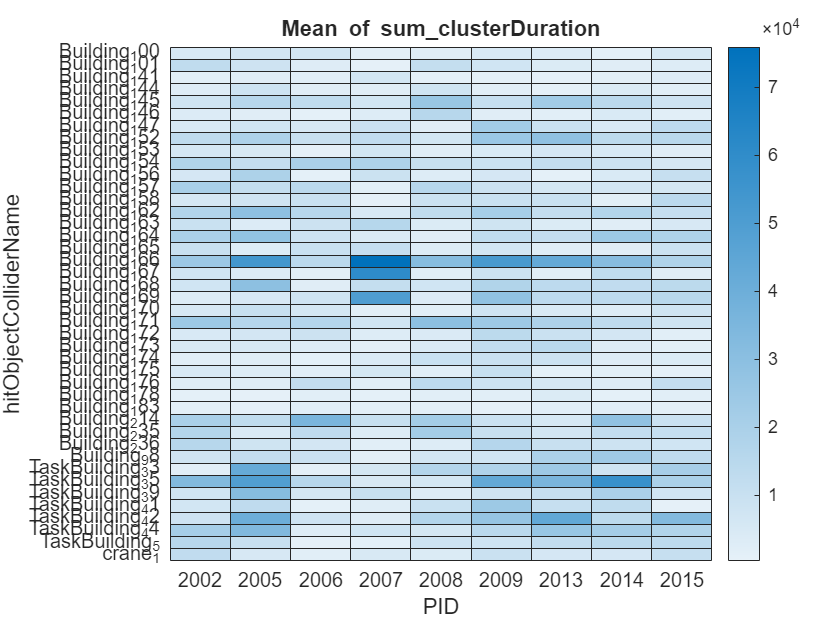

% heatmap of control participants only for sanity check
heatmap(common_buildings_control_sum_gaze, "PID", "hitObjectColliderName", "ColorVariable", "sum_clusterDuration")

% reorder participants to have a good heatmap
unique_parts = unique(excluded_sum_gaze.PID);

glaucoma_parts = p_table(p_table.category == "glaucoma", :);
glaucoma_parts = intersect(unique_parts, glaucoma_parts.PID);

control_parts = intersect(unique_parts, control_parts.PID);

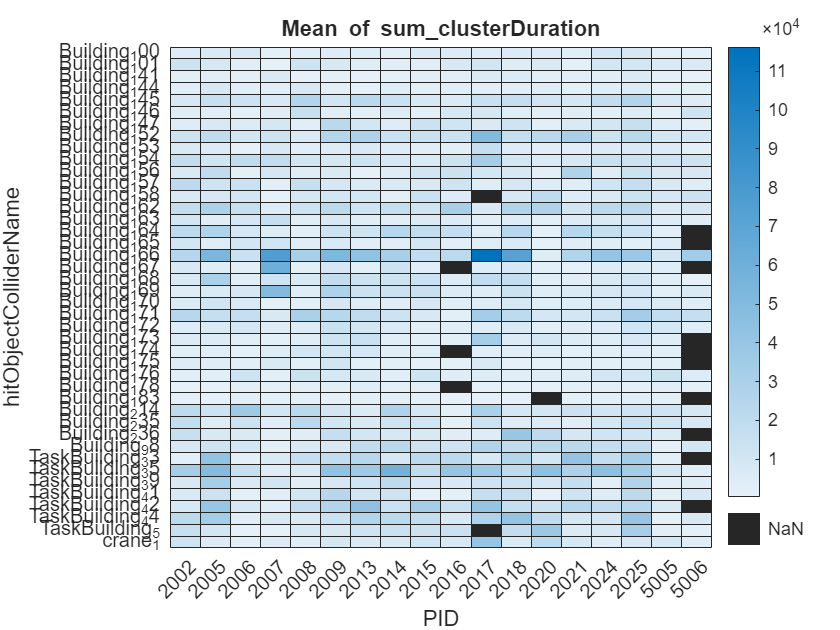

query = any(string(excluded_sum_gaze.hitObjectColliderName) == string(common_buildings)', 2);
commong_buildings_excluded_sum_gaze = excluded_sum_gaze(query, :);
% 
h = heatmap(commong_buildings_excluded_sum_gaze, "PID", "hitObjectColliderName", "ColorVariable", "sum_clusterDuration");
h.XDisplayData = [control_parts; glaucoma_parts];

#### Node Data Table

folder_path = fullfile("F:\big-data\vr_data\Data\preprocessing-pipeline\graphs");
graph_table = create_glaucoma_graph_table(folder_path);

% hardcoded excluded parts defined above
query = any(graph_table.PID == p_table.PID', 2);
excluded_graph_table = graph_table(query, :);

% summary connectivity table is the one with full graph to normalize
% everything across all subjects.
summary_connectivity_table = groupsummary(excluded_graph_table, {'PID'}, {'mean', 'std'}, 'connections');

% excluding buildings that are not considered by participants
% the rationale might be that participants are not aware of ROI in the city
% This might lead them to focus on the things by which they already got
% attended.
std_graph_table = excluded_graph_table(excluded_graph_table.connections > 0, :);
standard_summary_connectivity_table = groupsummary(std_graph_table, {'PID'}, {'mean', 'std'}, 'connections');

analyzed_p_data = [control_parts; glaucoma_parts];
[r, ~] = find(p_table.PID == analyzed_p_data');
categories = p_table.category(r);

#### Run ANOVA for Connectivity

[r, ~] = find(standard_summary_connectivity_table.PID == analyzed_p_data');

Normality Tests:
Group control: p = 0.0841, Normal


Group glaucoma: p = 0.5000, Normal

Homogeneity of Variance Test:


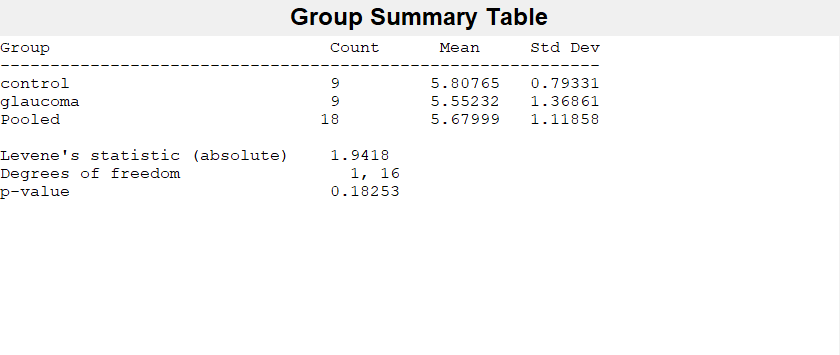

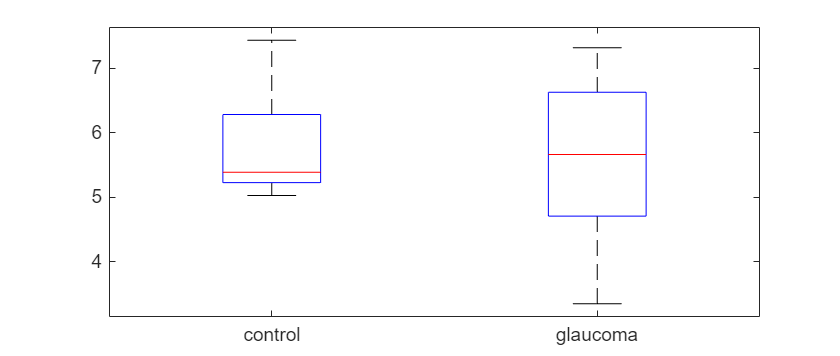

Levene test: p = 0.1825, Equal variances

ANOVA Results:


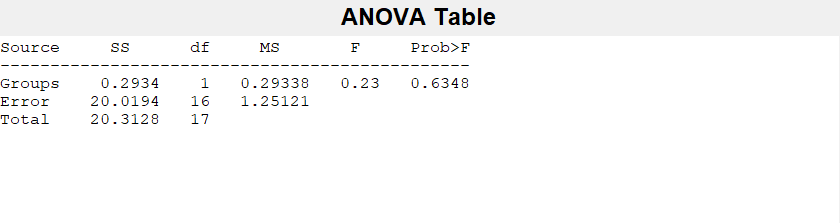

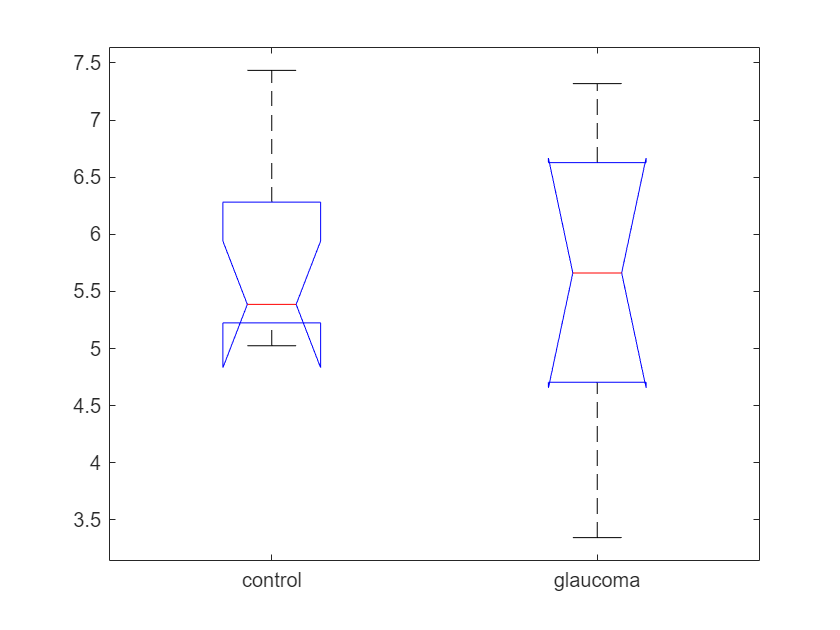

% without correction for mean connections
connectivity_data = standard_summary_connectivity_table.mean_connections(r);
run_anova(connectivity_data, categories);

Normality Tests:
Group control: p = 0.2558, Normal
Group glaucoma: p = 0.1494, Normal

Homogeneity of Variance Test:


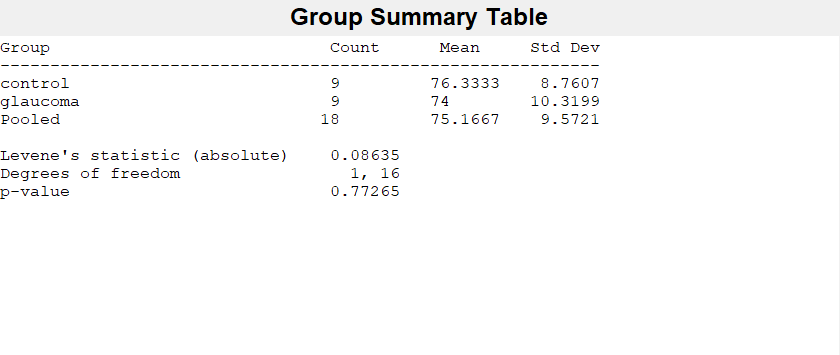

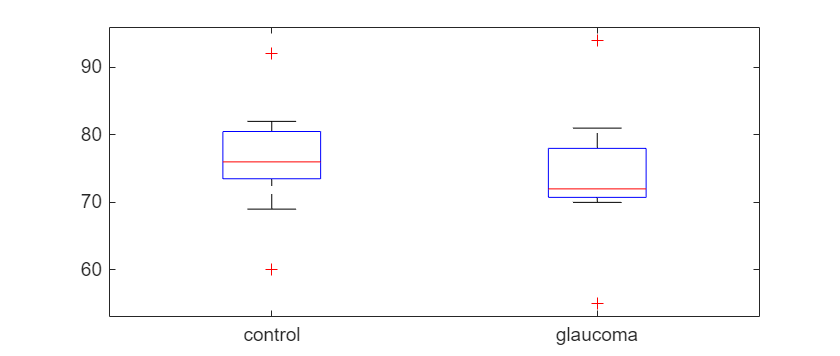

Levene test: p = 0.7726, Equal variances

ANOVA Results:


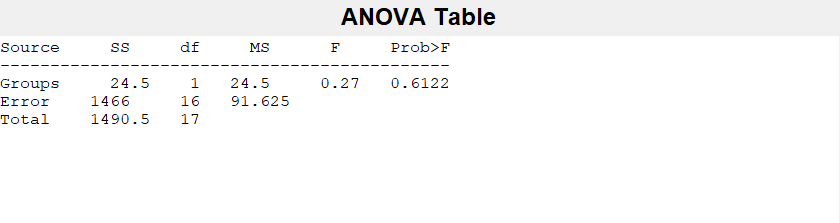

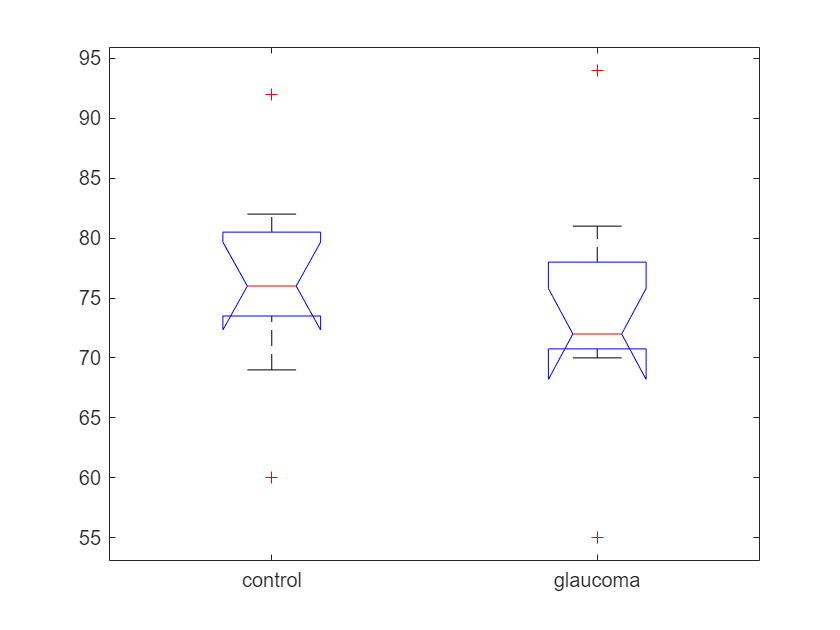

% building count
count_data = standard_summary_connectivity_table.GroupCount(r);
run_anova(count_data, categories);

Normality Tests:
Group control: p = 0.0693, Normal


Group glaucoma: p = 0.5000, Normal

Homogeneity of Variance Test:


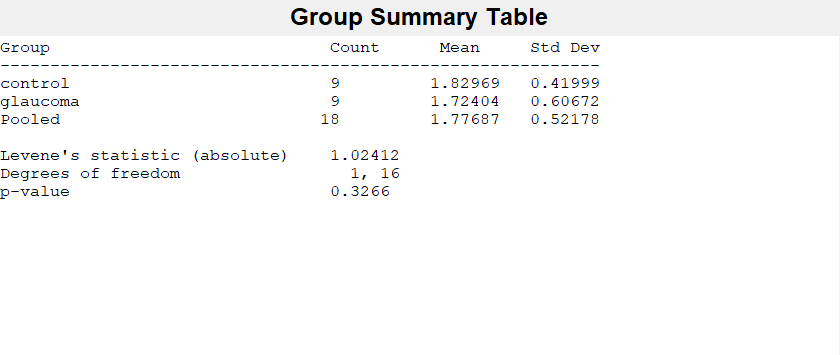

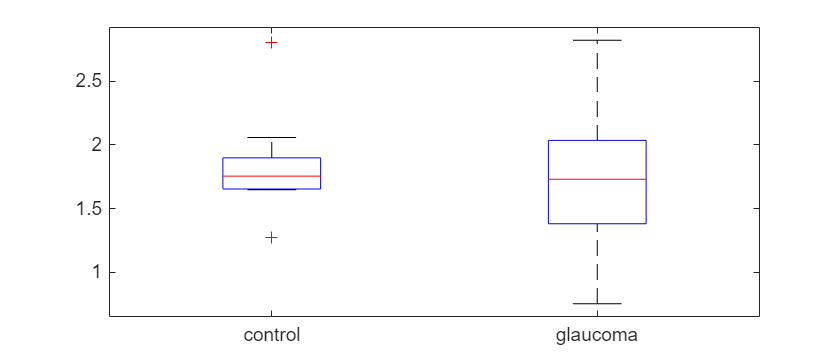

Levene test: p = 0.3266, Equal variances

ANOVA Results:


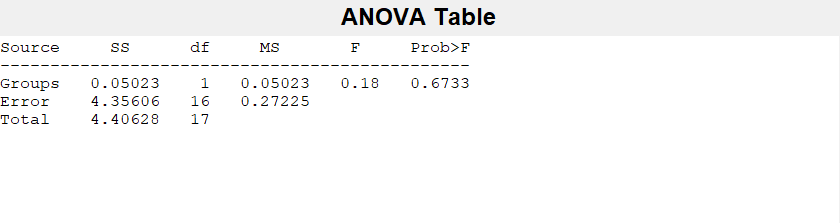

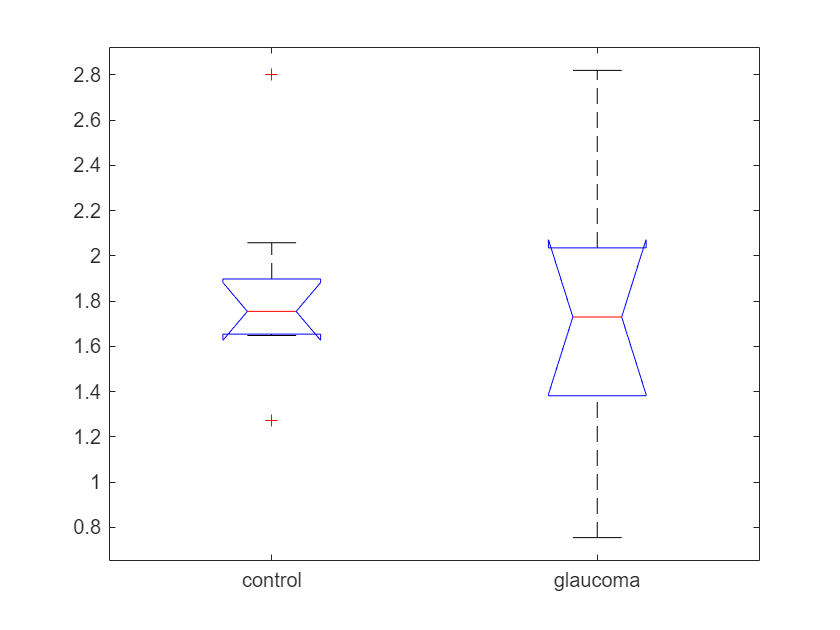

% with correction for mean connections
connectivity_data = summary_connectivity_table.mean_connections(r);
run_anova(connectivity_data, categories);

#### Run ANOVA for Fixation Related Measure

Normality Tests:
Group control: p = 0.0499, Not normal
Group glaucoma: p = 0.4573, Normal

Homogeneity of Variance Test:


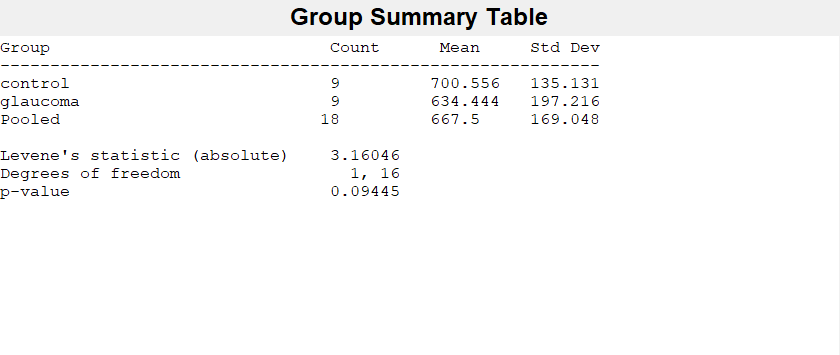

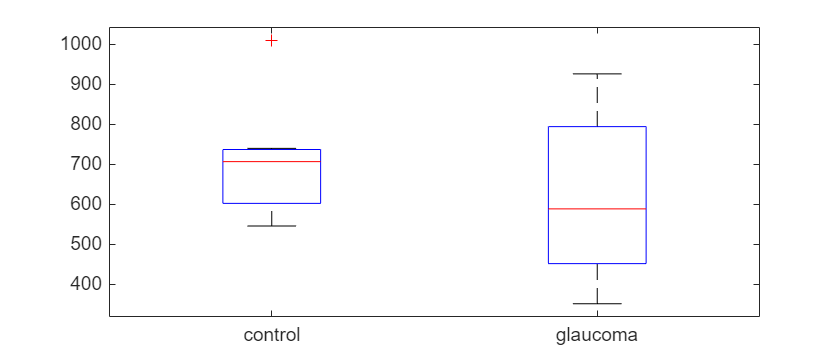

Levene test: p = 0.0945, Equal variances

ANOVA Results:


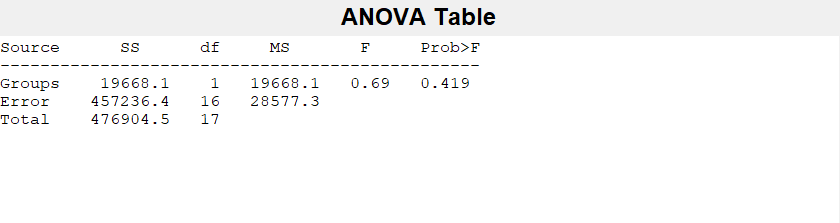

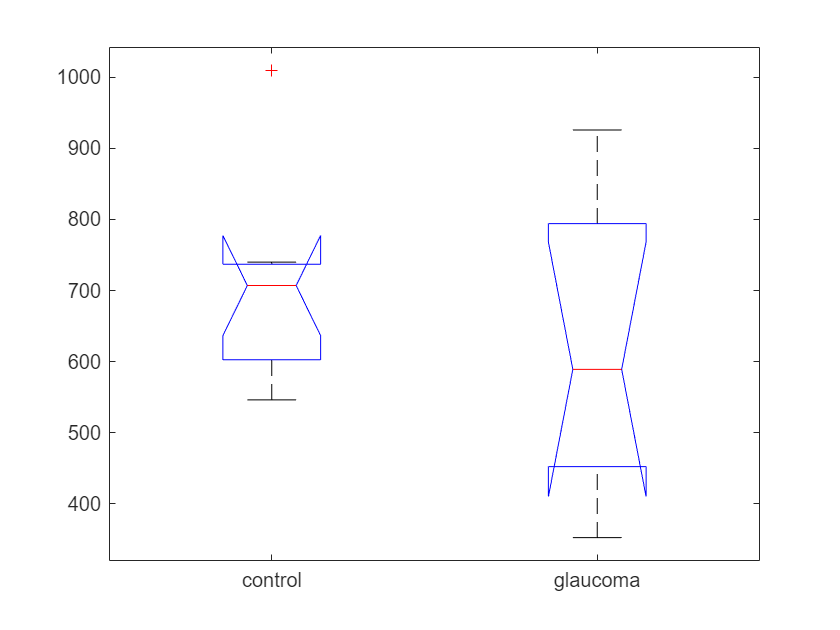

% check # of fixation
[r, ~] = find(no_fixation.PID == analyzed_p_data');

data = no_fixation.GroupCount(r);
run_anova(data, categories);

#### Run GLME for Fixation Data Full (no aggregation)

test_check = run_glme_preliminary_tests( ...
    gaze_full_group, ...
    "clusterDuration", ...
    {"category"}, ...
    "PID" ...
    );

print_struct(test_check);

missing_data             : (table)
has_missing              : false
response_stats           : (struct)
    mean    : 0.847905
    variance: 1.35747
    min     : 0.26661
    max     : 27.3282
is_binary                : false
is_count                 : false
number_of_groups         : 18
min_group_size           : 352
max_group_size           : 1010
mean_group_size          : 667.5
sufficient_groups        : true
recommended_distribution : "gamma"
recommended_link         : "log"
normality_p              : 0.001
is_normal                : false
notes                    : "Non-normal positive data; consider gamma distribution"
recommended_formula      : "clusterDuration  ~  category  + (1| PID )"
total_observations       : 12015
predictors_count         : 1
observations_per_variable: 12015
adequate_sample          : true


% data should be close by, not need to search above
gaze_full_group_median = groupsummary(gaze_full_group, ["PID", "hitObjectColliderName", "category"], "median", "clusterDuration");
gaze_full_group_median.PID = categorical(gaze_full_group_median.PID);
gaze_full_group_median.category = categorical(gaze_full_group_median.category);
gaze_full_group_median.hitObjectColliderName = categorical(gaze_full_group_median.hitObjectColliderName);

% removing some buildings is necessary as the matrix is not singular. Only
% one or two participants look at those buildings.
% Adding (1 | hitObjectColliderName) is not working. Need to find a way to
% integrate into the model.



[res_full, sum_full] = fit_and_interpret_glme(gaze_full_group_median, "median_clusterDuration ~ category + (1 | hitObjectColliderName)", "gamma");

=== Model Summary ===
    "Formula: "    "median_clusterDuration ~ category + (1 | hitObjectColliderName)"

    "Distribution: "    "gamma"    " with "    "reciprocal"    " link"

AIC: 3505.8908, BIC: 3526.7312
=== Coefficient Interpretations ===
(Intercept): Baseline value when all predictors are zero/reference level
category_glaucoma: Coefficient = -0.1916 (p=0.0000). Interpret based on link function reciprocal
=== Random Effects ===
    0.4334
   -0.0776
    0.0782
    0.3737
    0.1564
   -0.1719
    0.2940
    0.1546
    0.1372
    0.3076
   -0.1234
    0.2845
    0.2154
    0.4512
   -0.2614
    0.2674
    0.2432
   -0.3440
   -0.0744
    0.0208
    0.2918
    0.1992
   -0.2263
    0.3919
   -0.0255
    0.3478
   -0.1461
   -0.0885
   -0.5420
    0.2249
    0.0555
    0.0550
   -0.0734
   -0.2176
   -0.1455
    0.0082
   -0.4670
    0.3239
   -0.3096
    0.1673
   -0.1289
   -0.5526
   -0.1266
   -0.3237
   -0.4995
   -0.0184
   -0.2291
    0.2589
    0.1076
   -0.1225
    0.0585

r2 = calculate_nakagawa_r2(res_full);

anv = anova(res_full);
disp(anv);


    ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat     DF1    DF2     pValue     
    {'(Intercept)'}        1378.2    1      1351    1.5868e-208
    {'category'   }        20.038    1      1351     8.2306e-06



% Residuals
r = residuals(res_full,'ResidualType','Pearson');
mufit = fitted(res_full);
scatter(mufit,r);
title('Residuals versus Fitted Values');
xlabel('Fitted Values');
ylabel('Residuals');

qqplot(r);


% Check data distribution
% CAUTION: It takes a lot of time to generate as it's vectorized not rasterized.
tiledlayout(3, 8);
for dummy_p = analyzed_p_data'
    nexttile;
    cur_data = gaze_full_group(gaze_full_group.PID == categorical(dummy_p), :);
    fit_normal(cur_data.clusterDuration);
end

#### Run GLME for Fixation Data Sum for Buildings

collider_sum_gaze_p = join(collider_sum_gaze, p_table);
collider_sum_gaze_p.category = reordercats(categorical(collider_sum_gaze_p.category), ["control", "glaucoma"]);
collider_sum_gaze_p.hitObjectColliderName = categorical(collider_sum_gaze_p.hitObjectColliderName);
collider_sum_gaze_p.PID = categorical(collider_sum_gaze_p.PID);
collider_sum_gaze_p.sum_clusterDuration = collider_sum_gaze_p.sum_clusterDuration / 1000;

tiledlayout(3, 8);
for dummy_p = analyzed_p_data'
    nexttile;
    cur_data = collider_sum_gaze_p(collider_sum_gaze_p.PID == categorical(dummy_p), :);
    fit_normal(cur_data.sum_clusterDuration);
end

test_check = run_glme_preliminary_tests( ...
    collider_sum_gaze_p, ...
    "sum_clusterDuration", ...
    {"category"}, ...
    "PID" ...
    );
print_struct(test_check);

[res_full, sum_full] = fit_and_interpret_glme(collider_sum_gaze_p, "sum_clusterDuration ~ category + (1 | PID) + (1 | hitObjectColliderName)", "gamma");

=== Model Summary ===
    "Formula: "    "sum_clusterDuration ~ category + (1 | PID) + (1 | hitObjectColliderName)"

    "Distribution: "    "gamma"    " with "    "reciprocal"    " link"

AIC: -728.3257, BIC: -702.2753
=== Coefficient Interpretations ===
(Intercept): Baseline value when all predictors are zero/reference level
category_glaucoma: Coefficient = 0.0002 (p=0.9650). Interpret based on link function reciprocal
=== Random Effects ===
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.2675
   -0.3533
   -0.3269
    0.5385
    0.3108
    0.2878
    0.5834
    0.3010
    0.2962
    0.4144
   -0.0212
    0.3042
   -0.0513
   -0.1006
   -0.0317
    0.4648
   -0.1737
   -0.4365
   -0.2828
   -0.3908
   -0.3400
   -0.1352
   -0.3807
    0.1151
   -0.4594
   -0.2890
   -0.4366
   -0.3819
   -0.3947
   -0.4015
   -0.3980
   -0.2196
  

r2 = calculate_nakagawa_r2(res_full);

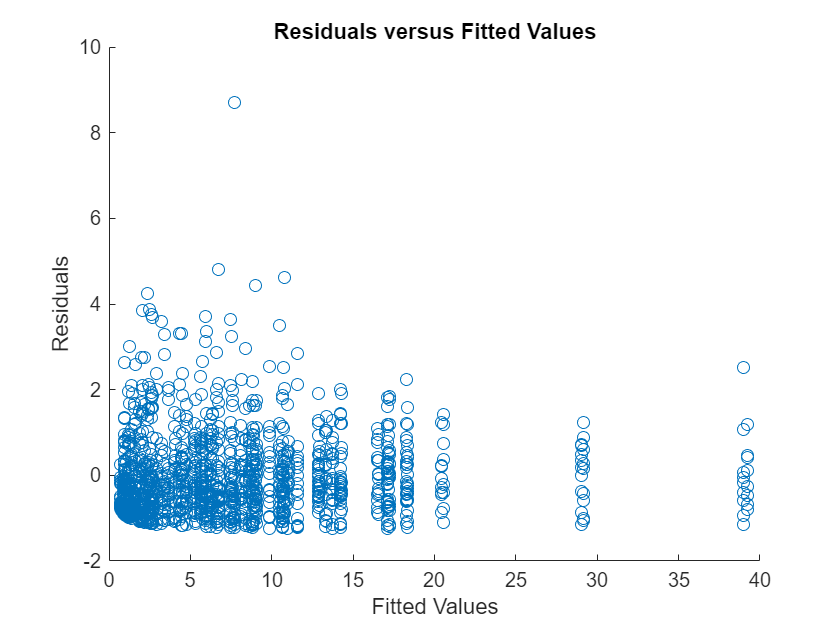



% Residuals
r = residuals(res_full,'ResidualType','Pearson');
mufit = fitted(res_full);
figure;
scatter(mufit,r);
title('Residuals versus Fitted Values');
xlabel('Fitted Values');
ylabel('Residuals');

qqplot(r);

#### Run GLME for Fixation Data and the Sum for Buildings with inside/outside

node_table = G.Nodes;
node_table.Name = categorical(node_table.Name);
gaze_full_group_io_building = join(gaze_full_group, node_table, ...
    "LeftKeys", "hitObjectColliderName", ...
    "RightKeys", "Name", ...
    "RightVariables", "inside");

test_check = run_glme_preliminary_tests( ...
    gaze_full_group_io_building, ...
    "clusterDuration", ...
    {"inside"}, ...
    "PID" ...
    );

print_struct(test_check);

missing_data             : (table)
has_missing              : false
response_stats           : (struct)
    mean    : 0.847905
    variance: 1.35747
    min     : 0.26661
    max     : 27.3282
is_binary                : false
is_count                 : false
number_of_groups         : 18
min_group_size           : 352
max_group_size           : 1010
mean_group_size          : 667.5
sufficient_groups        : true
recommended_distribution : "gamma"
recommended_link         : "log"
normality_p              : 0.001
is_normal                : false
notes                    : "Non-normal positive data; consider gamma distribution"
recommended_formula      : "clusterDuration  ~  inside  + (1| PID )"
total_observations       : 12015
predictors_count         : 1
observations_per_variable: 12015
adequate_sample          : true


median_gaze_full_group_io_building = groupsummary(gaze_full_group_io_building, ...
    ["PID", "hitObjectColliderName", "category", "inside"], ...
    "median", ...
    "clusterDuration");
[res_full, sum_full] = fit_and_interpret_glme(median_gaze_full_group_io_building, "median_clusterDuration ~ category + inside +  (1 | hitObjectColliderName)", "gamma");

=== Model Summary ===
    "Formula: "    "median_clusterDuration ~ category + inside +  (1 | hitObjectColliderName)"

    "Distribution: "    "gamma"    " with "    "reciprocal"    " link"

AIC: 3501.4092, BIC: 3527.4596
=== Coefficient Interpretations ===
(Intercept): Baseline value when all predictors are zero/reference level
category_glaucoma: Coefficient = -0.1902 (p=0.0000). Interpret based on link function reciprocal
inside_1: Coefficient = -0.4300 (p=0.0000). Interpret based on link function reciprocal
=== Random Effects ===
    0.2820
   -0.2252
   -0.0660
    0.2629
    0.1114
   -0.2694
    0.2065
    0.1060
    0.0903
    0.2275
   -0.1699
    0.1433
    0.0706
    0.2994
   -0.3988
    0.1621
    0.0946
   -0.4942
    0.1261
    0.2152
    0.4633
    0.3782
   -0.0181
    0.5548
    0.1719
    0.5174
    0.0589
    0.1111
   -0.3172
    0.4044
    0.2448
    0.2420
    0.1202
   -0.0100
    0.0595
    0.2034
   -0.2466
    0.4922
   -0.0955
    0.3451
    0.0751
   -0.3274


[res_nope, sum_nope] = fit_and_interpret_glme(median_gaze_full_group_io_building, "median_clusterDuration ~ category * inside +  (1 | hitObjectColliderName)", "gamma");

=== Model Summary ===
    "Formula: "    "median_clusterDuration ~ category * inside +  (1 | hitObjectColliderName)"

    "Distribution: "    "gamma"    " with "    "reciprocal"    " link"

AIC: 3490.8841, BIC: 3522.1446
=== Coefficient Interpretations ===
(Intercept): Baseline value when all predictors are zero/reference level
category_glaucoma: Coefficient = -0.2477 (p=0.0003). Interpret based on link function reciprocal
inside_1: Coefficient = -0.4818 (p=0.0000). Interpret based on link function reciprocal
category_glaucoma:inside_1: Coefficient = 0.0947 (p=0.2776). Interpret based on link function reciprocal
=== Random Effects ===
    0.2827
   -0.2255
   -0.0635
    0.2670
    0.1084
   -0.2823
    0.2051
    0.1111
    0.0953
    0.2360
   -0.1712
    0.1408
    0.0708
    0.3002
   -0.4010
    0.1656
    0.0948
   -0.4944
    0.1263
    0.2156
    0.4639
    0.3784
   -0.0193
    0.5559
    0.1722
    0.5191
    0.0589
    0.1104
   -0.3182
    0.4056
    0.2463
    0.2426
    0

comp_res = compare(res_full, res_nope);
r2 = calculate_nakagawa_r2(res_full);


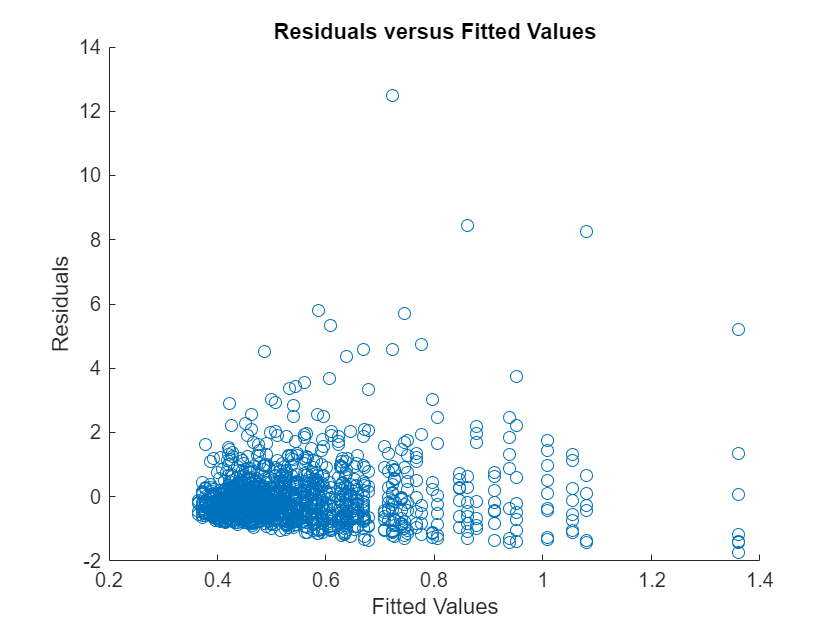

% Residuals

r = residuals(res_full,'ResidualType','Pearson');
mufit = fitted(res_full);
figure;
scatter(mufit,r);
title('Residuals versus Fitted Values');
xlabel('Fitted Values');
ylabel('Residuals');

[beta, beta_SE, stats] = fixedEffects(res_full);

% Confidence level
alpha = 0.05; % 95% confidence level
t_value = tinv(1 - alpha/2, stats.DF);

beta(2:end) = beta(1) + beta(2:end);
stats.SE(2:end) = sqrt(stats.SE(1)^2 + stats.SE(2:end).^2);

% Compute Confidence Intervals
CI_fixedEffects = [beta - t_value .* stats.SE, beta + t_value .* stats.SE];

% Display results
disp('Fixed Effect Estimates and 95% Confidence Intervals:');

Fixed Effect Estimates and 95% Confidence Intervals:


table(beta, stats.SE, CI_fixedEffects(:,1), CI_fixedEffects(:,2), ...
    'VariableNames', {'Estimate', 'SE', 'Lower_95CI', 'Upper_95CI'})

ans = 3×4 table
    Estimate       SE       Lower_95CI    Upper_95CI
    ________    ________    __________    __________

     2.2806     0.070447      2.1424        2.4188  
     2.0904     0.082439      1.9287        2.2521  
     1.8506      0.12089      1.6135        2.0878  


#### The filter effect of node degree centrality

dummy_table = excluded_graph_table;
dummy_table.nodes = categorical(dummy_table.nodes);
dummy_table.PID = categorical(dummy_table.PID);
gaze_full_group_io_building_node = join(gaze_full_group_io_building, dummy_table, ...
    "LeftKeys", ["PID", "hitObjectColliderName"], ...
    "RightKeys", ["PID", "nodes"], ...
    "RightVariables", "connections");

median_gaze_full_group_io_building_node = groupsummary(gaze_full_group_io_building_node, ["PID", "hitObjectColliderName", "category", "inside", "connections"], "median", "clusterDuration");
% median_gaze_full_group_io_building_node = gaze_full_group_io_building_node
query = median_gaze_full_group_io_building_node.connections > 10;
% median_gaze_full_group_io_building_node = median_gaze_full_group_io_building_node(query, :);
median_gaze_full_group_io_building_node.is_landmark = query;

[res_full, sum_full] = fit_and_interpret_glme(median_gaze_full_group_io_building_node, "median_clusterDuration ~ category + inside + is_landmark + (1 | PID)", "gamma");

=== Model Summary ===
    "Formula: "    "median_clusterDuration ~ category + inside + is_landmark + (1 | PID)"

    "Distribution: "    "gamma"    " with "    "reciprocal"    " link"

AIC: 3892.2964, BIC: 3923.5569
=== Coefficient Interpretations ===
(Intercept): Baseline value when all predictors are zero/reference level
category_glaucoma: Coefficient = -0.1627 (p=0.2126). Interpret based on link function reciprocal
inside_1: Coefficient = -0.3422 (p=0.0000). Interpret based on link function reciprocal
is_landmark_1: Coefficient = 0.1731 (p=0.0616). Interpret based on link function reciprocal
=== Random Effects ===
    0.0835
   -0.1515
    0.1810
    0.1696
    0.0318
    0.1279
   -0.1109
   -0.0961
   -0.2353
    0.0068
    0.1595
    0.1185
   -0.5071
   -0.1811
    0.3536
   -0.4195
    0.2864
    0.1828



[res_nope, sum_nope] = fit_and_interpret_glme(median_gaze_full_group_io_building_node, "median_clusterDuration ~ connections + (1 | hitObjectColliderName)", "gamma");

=== Model Summary ===
    "Formula: "    "median_clusterDuration ~ connections + (1 | hitObjectColliderName)"

    "Distribution: "    "gamma"    " with "    "reciprocal"    " link"

AIC: 3479.6856, BIC: 3500.5259
=== Coefficient Interpretations ===
(Intercept): Baseline value when all predictors are zero/reference level
connections: Coefficient = 0.0282 (p=0.0002). Interpret based on link function reciprocal
=== Random Effects ===
    0.3834
   -0.1457
    0.0440
    0.4428
    0.2153
   -0.1012
    0.3707
    0.1739
    0.1538
    0.3417
   -0.1008
    0.3466
    0.2207
    0.4781
   -0.2253
    0.3301
    0.2473
   -0.4159
   -0.0519
   -0.0728
    0.2300
    0.2026
   -0.3394
    0.4188
   -0.2086
    0.3379
   -0.3351
   -0.1535
   -0.5716
    0.0992
   -0.0064
    0.0845
   -0.0899
   -0.2332
   -0.2498
   -0.0640
   -0.5155
    0.3483
   -0.5324
    0.1650
   -0.2000
   -0.5858
   -0.1738
   -0.4573
   -0.5267
   -0.0663
   -0.2402
    0.2607
    0.0520
   -0.0965
    0.0956
   

comp_res = compare(res_full, res_nope);
r2 = calculate_nakagawa_r2(res_full);

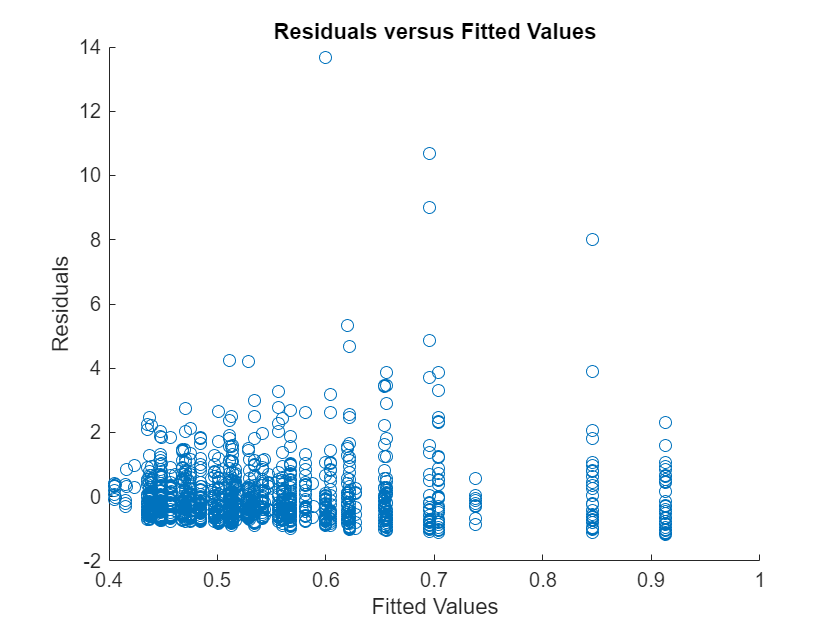

% Residuals

r = residuals(res_full,'ResidualType','Pearson');
mufit = fitted(res_full);
figure;
scatter(mufit,r);
title('Residuals versus Fitted Values');
xlabel('Fitted Values');
ylabel('Residuals');